# **Matlab Bootcamp**

# Recap

#### Numeric Arrays

- e.g. list of phone numbers

- B = [4670456, 7640600, 123456];

#### Matrices

- e.g. list of GPS coordinates

- A  = [42.3086,-83.6921; 82.208, 23.692];

#### Cell Arrays

- e.g. list of names

- C = {'Duck','Goose','Crane'};

# Matrix Manipulation

#### Adding a scalar to an array

A = [1;2;3;4];
A + 3

ans =      4
     5
     6
     7


#### Adding two arrays

B = [3;4;5;6];
A + B

ans =      4
     6
     8
    10


#### Element-wise multiplication

A.*B

ans =      3
     8
    15
    24


#### Matrix multiplication

C = [5 10 15 20];
A*C

ans =      5    10    15    20
    10    20    30    40
    15    30    45    60
    20    40    60    80


# Organizing variables into structures

### Structures

Structure arrays can be used to group related data together. The data is structure arrays is accessed by name.

patient(1).name = 'Jane Smith';
patient(1).age = 28;
patient(1).results = [68, 70, 68; 72, 81, 69; 172, 170, 169];
patient(1)

ans = struct with fields:
       name: 'Jane Smith'
    billing: 28.5000
       test: [3×3 double]
        age: 28
    results: [3×3 double]


### Tables

Tables are used for storing data in rows and column-oriented variables.

- Tables can contain different data types, such as strings and doubles

- Each variable in the table must have the same number of rows

Use *readtable* to import example patient data and then *summary to *examine its contents:

T=readtable('patients.dat');
summary(T)


Variables:

    LastName: 100×1 cell array of character vectors

    Gender: 100×1 cell array of character vectors

    Age: 100×1 double

        Values:

            Min        25  
            Median     39  
            Max        50  

    Location: 100×1 cell array of character vectors

    Height: 100×1 double

        Values:

            Min          60   
            Median       67   
            Max          72   

    Weight: 100×1 double

        Values:

            Min          111  
            Median     142.5  
            Max          202  

    Smoker: 100×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    Systolic: 100×1 double

        Values:

            Min          109    
            Median       122    
            Max          138    

    D

Display data for the first four patients:

T(1:4,:)

ans = 4×10 table
     LastName      Gender     Age             Location              Height    Weight    Smoker    Systolic    Diastolic    SelfAssessedHealthStatus
    __________    ________    ___    ___________________________    ______    ______    ______    ________    _________    ________________________

    'Smith'       'Male'      38     'County General Hospital'        71       176        1         124          93              'Excellent'       
    'Johnson'     'Male'      43     'VA Hospital'                    69       163        0         109          77              'Fair'            
    'Williams'    'Female'    38     'St. Mary's M

Now create a table that only includes the patient age, height and weight:

T2=table(T.Age,T.Height,T.Weight);
T2.Properties.VariableNames={'Age','Height','Weight'}

T2 = 100×3 table
    Age    Height    Weight
    ___    ______    ______

    38       71       176  
    43       69       163  
    38       64       131  
    40       67       133  
    49       64       119  
    46       68       142  
    33       64       142  
    40       68       180  
    28       68       183  
    31       66       132  
    45       68       128  
    42       66       137  
    25       71       174  
    39       72       202  
    36       65       129  
    48       71       181  


# Framington Heart Disease Dataset

This dataset comes from a landmark study that analyzed ~14,000 people from three generations. The findings have informed the understanding of factors that impact cardiovascular health.  

Import the dataset and determine its size:

fram = readtable('frmgham2.xls');
size(fram)

ans =        11627          39


The output of *size *indiciates that the dataset includes 11,627 rows and 39 columns. Display the names of the 39 columns:

fram.Properties.VariableNames

ans = 1×39 cell array
    {'RANDID'}    {'SEX'}    {'TOTCHOL'}    {'AGE'}    {'SYSBP'}    {'DIABP'}    {'CURSMOKE'}    {'CIGPDAY'}    {'BMI'}    {'DIABETES'}    {'BPMEDS'}    {'HEARTRTE'}    {'GLUCOSE'}    {'educ'}    {'PREVCHD'}    {'PREVAP'}    {'PREVMI'}    {'PREVSTRK'}    {'PREVHYP'}    {'TIME'}    {'PERIOD'}    {'HDLC'}    {'LDLC'}    {'DEATH'}    {'ANGINA'}    {'HOSPMI'}    {'MI_FCHD'}    {'ANYCHD'}    {'STROKE'}    {'CVD'}    {'HYPERTEN'}    {'TIMEAP'}    {'TIMEMI'}    {'TIMEMIFC'}    {'TIMECHD'}    {'TIMESTRK'}    {'TIMECVD'}    {'TIMEDTH'}    {'TIMEHYP'}


### Extracting Simple Properties

Determine the mean, median and range of BMI:

mean(fram.BMI)
median(fram.BMI)

ans = NaN

range(fram.BMI)

ans = NaN

The mean and median functions return *NaN *because there is data missing from the BMI array. MATLAB also has functions that ignore these missing data points:

nanmean(fram.BMI)

ans = 42.3700

nanmedian(fram.BMI)

We will now look at extracting data from the framingham data set based on certain criteria. For example, what if we only want to examine individuals who smoke?

smoker_rows = fram.CURSMOKE==1;

ans = 25.8773

fram(smoker_rows,:)

ans = 25.4800

Similarly, we can pick out individuals with a BMI above 30:

BMI_rows = fram.BMI>35;
fram(BMI_rows,:)

T = 5029×39 table
    RANDID    SEX    TOTCHOL    AGE    SYSBP    DIABP    CURSMOKE    CIGPDAY     BMI     DIABETES    BPMEDS    HEARTRTE    GLUCOSE    educ    PREVCHD    PREVAP    PREVMI    PREVSTRK    PREVHYP    TIME    PERIOD    HDLC    LDLC    DEATH    ANGINA    HOSPMI    MI_FCHD    ANYCHD    STROKE    CVD    HYPERTEN    TIMEAP    TIMEMI    TIMEMIFC    TIMECHD    TIMESTRK    

This selection criteria method can also be applied to multiple variables at once:

SMOKER_BMI_rows = fram.CURSMOKE==1 & fram.BMI>35;
fram(SMOKER_BMI_rows,:)

By scrolling through the CURSMOKE and BMI columns of the above table, we can confirm that the new table only includes data for individuals that both smoked and have a BMI above 35. Now create a table which only includes the age, cholesterol and heartrate for these individuals:

vars = {'AGE','TOTCHOL','HEARTRTE'};

T2 = 318×39 table
      RANDID      SEX    TOTCHOL    AGE    SYSBP    DIABP    CURSMOKE    CIGPDAY     BMI     DIABETES    BPMEDS    HEARTRTE    GLUCOSE    educ    PREVCHD    PREVAP    PREVMI    PREVSTRK    PREVHYP    TIME    PERIOD    HDLC    LDLC    DEATH    ANGINA    HOSPMI    MI_FCHD    ANYCHD    STROKE    CVD    HYPERTEN    TIMEAP    TIMEMI    TIMEMIFC    TIMECHD    TIMESTRK    <s

new_table = fram(SMOKER_BMI_rows,vars)

We can also convert this table to a matrix, but we will lose the table headers, as MATLAB arrays can only contain one type of data.

new_array = table2array(new_table)

### Manipulating Datasets

As seen earlier in the BMI array, there are missing values throughout the dataset, which are signified by *NaN. *It is important to know how to both find and replace these missing values.

We can use the *find* and *isnan *functions to determine the rows where data is missing:

rows=find(isnan(fram.BMI))

ans = 84×39 table
      RANDID      SEX    TOTCHOL    AGE    SYSBP    DIABP    CURSMOKE    CIGPDAY     BMI     DIABETES    BPMEDS    HEARTRTE    GLUCOSE    educ    PREVCHD    PREVAP    PREVMI    PREVSTRK    PREVHYP    TIME    PERIOD    HDLC    LDLC    DEATH    ANGINA    HOSPMI    MI_FCHD    ANYCHD    STROKE    CVD    HYPERTEN    TIMEAP    TIMEMI    TIMEMIFC    TIMECHD    TIMESTRK    <s

Now we want to create a new array for BMI without the missing data points:

new_BMI = fram.BMI;
new_BMI(find(isnan(fram.BMI)))=[];

new_table = 84×3 table
    AGE    TOTCHOL    HEARTRTE
    ___    _______    ________

    42       206         70   
    48       208         75   
    61       326         57   
    60       180         88   
    44       229        104   
    56       153         75   
    48       268         72   
    60       247         78   
    73       NaN        NaN   
    55       233         80   
    67       192         55   
    42       199         80   
    46       212        110   
    51       250         94   
    62       206         80   
    36       248         65   


To confirm that this worked, we can check that the size of the BMI array has decreased and that the *mean *function now works:

mean(new_BMI)

new_array =     42   206    70     0
    48   208    75     0
    61   326    57     0
    60   180    88     1
    44   229   104     0
    56   153    75     1
    48   268    72     0
    60   247    78     0
    73   NaN   NaN     0
    55   233    80     0


Now that the missing data points have been removed, sort the BMI array:

sort(new_BMI)

rows =            2
         265
         347
         433
         795
        1216
        1300
        1527
        1894
        2631


ans = 11627×1 logical array
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0


We see that the default setting is to sort in ascending order, however there are multiple ways to use *sort.*

sort(new_BMI,'descend')

Next, let's look at the outliers in the BMI array:

[TF,L,U,C] = isoutlier(new_BMI)

Similar to the *isnan *function, *isoutlier *creates a new array, *TF, *and identify outlier points with ones. We can also see the lower and upper thresholds and the center value used to determine the outliers (variables L, U, and C). 

We can also add new data to our table. Add the *DIABETES* data to table *T4:*

new_table.DIABETES = fram.DIABETES(SMOKER_BMI_rows)

ans = 25.8773

###  Simple Analyses of the Dataset

We will now answer a few questions about the Framingam data set.

*1.) How many patients over 45 have a BMI over 40? *

patients = fram(fram.AGE>45 & fram.BMI>40,["AGE","BMI"]);

ans =    14.4300
   14.5300
   15.1600
   15.3200
   15.3300
   15.5400
   15.6400
   15.9200
   15.9600
   15.9600


size(patients)

*Another method:*

sum(fram.AGE>45 & fram.BMI>40)

ans =    56.8000
   56.8000
   56.8000
   55.3100
   52.9400
   51.2800
   48.6400
   47.2200
   46.5200
   45.9800


*2.) How data points are missing for the patient cholesterol? What is the median value for the cholesterol data that we do have?*

numel(find(isnan(fram.TOTCHOL)))

TF = 11575×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


L = 14.5384

U = 36.4216

C = 25.4800

nanmedian(fram.TOTCHOL)

*3.) Create a structure with all of the patient IDs and find the number of unique IDs.*

ID = fram.RANDID

new_table = 84×4 table
    AGE    TOTCHOL    HEARTRTE    DIABETES
    ___    _______    ________    ________

    42       206         70          0    
    48       208         75          0    
    61       326         57          0    
    60       180         88          1    
    44       229        104          0    
    56       153         75          1    
    48       268         72          0    
    60       247         78          0    
    73       NaN        NaN          0    
    55       233         80          0    
    67       192         55          1    
    42       199         80          0    
    46       212        110          0    
    51       250         94          0    
    62       206         80          0    
    36       248         65          0    


num_ID = numel(ID)
num_unq = numel(unique(ID))

# Importing and Exporting Datasets

### Importing

As of MATLAB 2019, the *readmatrix *function is recommended for importing datasets as opposed to previously used functions *csvread, xlsread, *and *dlmread*. *readmatrix *can be used with many different file types, such as .txt, .dat, .csv, and .xls. However, only numeric data can imported.

M = readmatrix("csv1.csv")

If you wish to create a table instead of an array, the *readtable *function should be used:

T = readtable("csv2.csv")

ans =     65     2


### Exporting

Similar to importing, the functions *xlswrite, dlmwrite, *and *csvwrite *are no longer recommended in MATLAB 2019. Instead, you should use *writetable *or *writematrix.* 

 Write the array we made earlier, *new_array, *to an Excel file:

writematrix(new_array,'new_array.xls')

ans = 65

readmatrix("new_array.xls")

Now do the same thing with *new_table, *except write to a text file:

writetable(new_table,'new_table.txt','WriteRowNames',true)

ans = 409

readtable('new_table.txt')

ans = 238

# Handling Big Datasets

### Head and Tail

The *head *and *tail *functions can be used to view the first and last rows of a table or array. The default for *heads *and *tails *is to display the first and last eight rows, respectively. However, the number of rows can be altered for each function. Consider the framingham dataset we used earlier:

first_rows = head(fram, 5)
last_rows = tail(fram,3)

ID =         2448
        2448
        6238
        6238
        6238
        9428
        9428
       10552
       10552
       11252


### Textscan

*textscan *can be used to read data from a text file or string and insert it into a cell array. Below, we use *textscan *to read the string *chr *and use ' %f ' to indicate that we want to output double-precision floating-point numbers.

chr = '0.41 8.24 3.57 6.24 9.27';

num_ID = 11627

C = textscan(chr,'%f');

num_unq = 4434

celldisp(C)

# Storing Big Datasets

### Datastore

Datastores allow you to work with large data sets in small pieces which fit into the memory, as opposed to loading the entire data set into the memory at once. Datastores also let you import and process data that is stored in multiple locations as a single database. However, each file in a datastore must contain the same type of data in the same order. 

There are several different kind of datastores. For example, tabular text datastores are for text files containing column-oriented data, such as txt or CSV files. Create a text file version of the Framingham data set and then create a datastore from that file:

writetable(fram,'fram.txt','WriteRowNames',true);

M =      1     6
     2     7
     3     8
     4     9
     5    10


ds = tabularTextDatastore('fram.txt')
preview(ds)

We can use *SelectVariableNames *to specify the columns that we want to look at:

ds.SelectedVariableNames = {'SYSBP','DIABP'};

T = 5×2 table
    Numbers    Letters
    _______    _______

       1         'A'  
       2         'B'  
       3         'C'  
       4         'D'  
       5         'E'  


preview(ds)

If all of the data in the datastore fits in memory, you can use the *readall *function. Otherwise, you must read the data in smaller sections which do fit in the memory. The default setting reads the datastore 20,000 rows at a time, but this can be adjusted:

ds.ReadSize = 10000;

### Sparces Matrices

Sparse matrices are useful when your dataset is comprised of mostly zeros. As opposed to normal matrices which store every elemnt in the matrix, sparce matrices only store the nonzero elements along with their row indices. Sparce matrices therefor require much less memory for storage than full matrices.

The first step in creating a sparse matrix is determining the density on nonzero elements. The lower the density, the more it makes sense to create a sparce matrix. Consider the below matrix A:

A = [0 0 0 5; 0 2 0 0; 1 3 0 0; 0 0 4 0]

ans =     42   206    70     0
    48   208    75     0
    61   326    57     0
    60   180    88     1
    44   229   104     0
    56   153    75     1
    48   268    72     0
    60   247    78     0
    73   NaN   NaN     0
    55   233    80     0


nnz(A) / numel(A)
S = sparse(A)

The output of *sparse *shows the nonzero elements and their respective indeces, sorted by column. You can then convert the sparse matrix back into the full matrix with the *full *command:

A = full(S)

It is also possible to create a sparse matrix directly from the nonzero elements, without needing the full matrix:

*S = sparse(i, j, s, m, n);*

- i, j = row and column indices, respectively

- s = vector of nonzero values with indices i, j

- m, n = row and column dimensions of resulting matrix, respectively

S = sparse([3 2 3 4 1],[1 2 2 3 4],[1 2 3 4 5],4,4)

ans = 84×4 table
    AGE    TOTCHOL    HEARTRTE    DIABETES
    ___    _______    ________    ________

    42       206         70          0    
    48       208         75          0    
    61       326         57          0    
    60       180         88          1    
    44       229        104          0    
    56       153         75          1    
    48       268         72          0    
    60       247         78          0    
    73       NaN        NaN          0    
    55       233         80          0    
    67       192         55          1    
    42       199         80          0    
    46       212        110          0    
    51       250         94          0    
    62       206         80          0    
    36       248         65          0    


# Plotting Datasets

We will quickly run through some of the plotting options in MATLAB, starting with a **2-D line plot**:

x = linspace(0,10,25);

first_rows = 5×39 table
    RANDID    SEX    TOTCHOL    AGE    SYSBP    DIABP    CURSMOKE    CIGPDAY     BMI     DIABETES    BPMEDS    HEARTRTE    GLUCOSE    educ    PREVCHD    PREVAP    PREVMI    PREVSTRK    PREVHYP    TIME    PERIOD    HDLC    LDLC    DEATH    ANGINA    HOSPMI    MI_FCHD    ANYCHD    STROKE    CVD    HYPERTEN    TIMEAP    TIMEMI    TIMEMIFC    TIMECHD    TIMESTRK    

y = cos(x);

last_rows = 3×39 table
      RANDID      SEX    TOTCHOL    AGE    SYSBP    DIABP    CURSMOKE    CIGPDAY     BMI     DIABETES    BPMEDS    HEARTRTE    GLUCOSE    educ    PREVCHD    PREVAP    PREVMI    PREVSTRK    PREVHYP    TIME    PERIOD    HDLC    LDLC    DEATH    ANGINA    HOSPMI    MI_FCHD    ANYCHD    STROKE    CVD    HYPERTEN    TIMEAP    TIMEMI    TIMEMIFC    TIMECHD    TIMESTRK 

After creating these variables, you can select them in the Workspace, go to Plots tab, and select the 2-D line plot. 

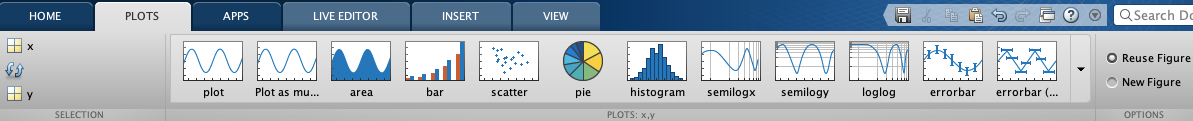

MATLAB will then create the plot for you and display the plotting command in the command line:

plot(x,y)

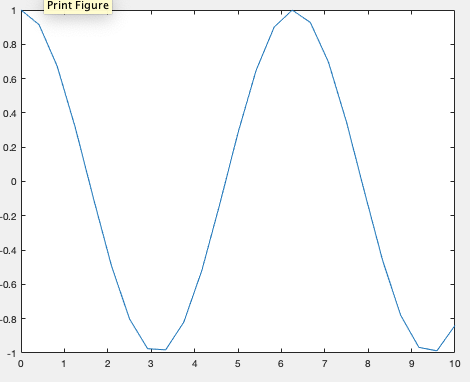

Once the figure has been created, you can use the Insert tab to add elements such as axis labels and titles. When you are done creating your plot, go to the File tab to generate the code.

If you do not wish to use the Plots tab, you can directly make the plots in your script with the appropriate command.

#### **Log-Log**

l1 = logspace(-1,2);

 
C{1} =
 
     []
 


l2 = exp(l1);
loglog(l1,l2,'-s')
grid on

#### **Bar Graphs**

x = 2000:2:2018;
y = [51 54 60 65 67 75 81 87 91 93];

ds =   TabularTextDatastore with properties:

                      Files: {
                             ' .../Documents/Michigan/Chandrasekaran Lab/AI in BME/Lecture 1/fram.txt'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
          ReadVariableNames: true
              VariableNames: {'RANDID', 'SEX', 'TOTCHOL' ... and 36 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: ','
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f', '%f', '%f' ... and 36 more}
                   TextType: 'char'
         ExponentCharacters: 'eEdD'
               CommentStyle: ''
                 Whitespace: ' \b\t'
    MultipleDelimitersAsOne: false

  Propertie

bar(x,y)

ans = 8×39 table
    RANDID    SEX    TOTCHOL    AGE    SYSBP    DIABP    CURSMOKE    CIGPDAY     BMI     DIABETES    BPMEDS    HEARTRTE    GLUCOSE    educ    PREVCHD    PREVAP    PREVMI    PREVSTRK    PREVHYP    TIME    PERIOD    HDLC    LDLC    DEATH    ANGINA    HOSPMI    MI_FCHD    ANYCHD    STROKE    CVD    HYPERTEN    TIMEAP    TIMEMI    TIMEMIFC    TIMECHD    TIMESTRK    

#### **Pie Chart**

p = [3 1 5 8 2];
pie(p)

ans = 8×2 table
    SYSBP    DIABP
    _____    _____

      106      70 
      121      66 
      121      81 
      105    69.5 
      108      66 
    127.5      80 
      141      89 
      150      95 


#### **Histograms**

Plot a histogram of 500 random numbers into 20 equally spaced bins:

x = randn(500,1);
nbins = 20;
h = histogram(x,nbins)

**Boxplots**

load carsmall

A =      0     0     0     5
     0     2     0     0
     1     3     0     0
     0     0     4     0


boxplot(MPG,Origin)

ans = 0.3125

title('Miles per Gallon by Vehicle Origin')

S =    (3,1)        1
   (2,2)        2
   (3,2)        3
   (4,3)        4
   (1,4)        5


xlabel('Country of Origin')
ylabel('Miles per Gallon (MPG)')

A =      0     0     0     5
     0     2     0     0
     1     3     0     0
     0     0     4     0


# Practice with Framingham Data

### Plot Age vs Frequency

age = framingham.AGE;

S =    (3,1)        1
   (2,2)        2
   (3,2)        3
   (4,3)        4
   (1,4)        5


histogram(age, 15)

title('Framingham: Age vs Frequency')
xlabel('Age')
ylabel('Frequency')

### Boxplot Sex vs Heart rate

sex = framingham.SEX;
HR = framingham.HEARTRTE;
boxplot(HR, sex,'Labels',{'Male','Female'})
legend('show')
title('Heart Rate vs Sex')
ylabel('Heart Rate')

### Education vs BMI - what is best way to show relationship?

educ = framingham.educ;
BMI = framingham.BMI;
boxplot(BMI,educ)

# Correlation

MATLAB has many tools for examining the relationship between variables. Use the *lsline *command to plot the least squares regression line for systolic and diastolic blood pressure. 

sys = framingham.SYSBP;
dia = framingham.DIABP;
scatter(sys,dia)
lsline

Next, calculate the correlation coefficient between systolic and diastolic blood pressure. The correlation coefficient, *r, *indicates the strength and direction of the relationship between the two variables.

r = corr(sys,dia)

We can also create a linear fit model for between the two variables using the *fitlm* command:

lrm = fitlm(sys,dia)

The output shows the model formula, the coefficients, and model summary. The coefficient of determination, r^2, is given in the model summary, but it can also be found with the below command:

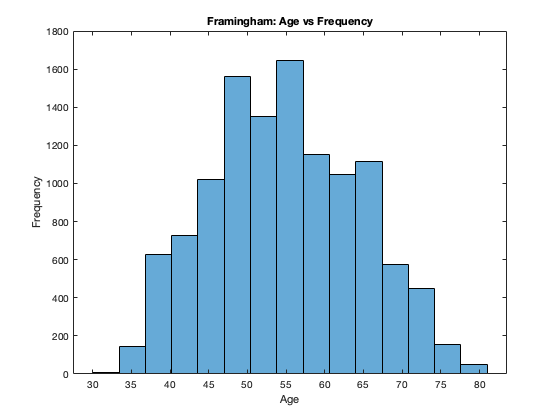

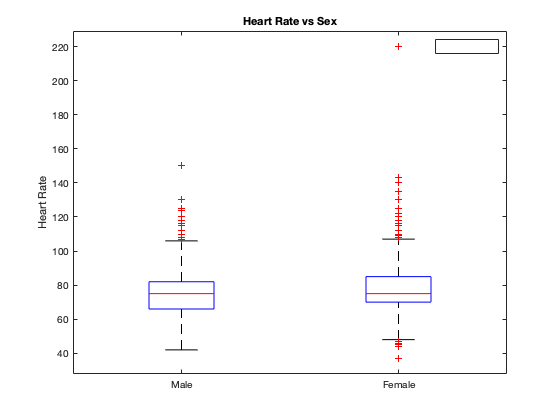

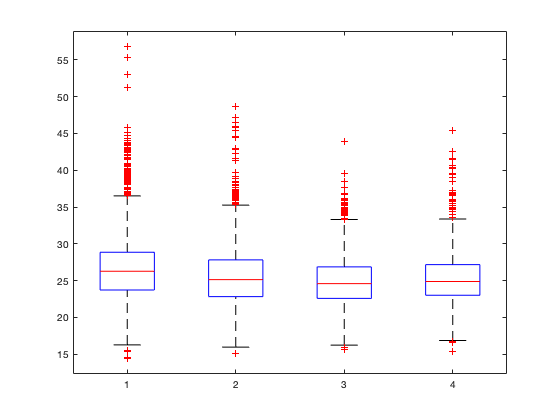

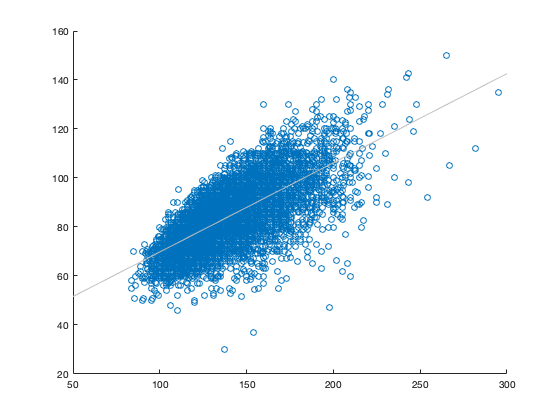

r = 0.7116

lrm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat     pValue
                   ________    _________    ______    ______

    (Intercept)     33.421       0.46061    72.558      0   
    x1             0.36396     0.0033325    109.22      0   


Number of observations: 11627, Error degrees of freedom: 11625
Root Mean Squared Error: 8.19
R-squared: 0.506,  Adjusted R-Squared: 0.506
F-statistic vs. constant model: 1.19e+04, p-value = 0

r2 = 0.5064

r2 = lrm.Rsquared.Ordinary

The coefficient of determination measures the amount of variance of one variable that can be explained by the other. In our example, r^2 is equal to 0.506. This means that 50.6% of the variance in the diastolic blood pressure can be explained by the systolic blood pressure data. This can be used as an indicator for how good of a fit the least squares regression line is. 